读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
sampling_points = 100000;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);
    MonteCarloSampling = ceil(rand(1, sampling_points) .* N);

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        for fd = -40:2:40
            cor = 0;
            for n = MonteCarloSampling
                cor = cor + ext_sur(n) * ext_ref_conj_shift(n) * exp(-1i * 2 * pi * fd/f_s * (n-1));
            end
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;

            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    range = 0:12:72;
    freqd = -40:2:40;
    [F,R]=meshgrid(freqd,range);
    surf(F,R,cors / cors_max);
    view(0,90);
    ylim([0 72]);
    xlim([-40 40]);
    xlabel("f_{d}(Hz)");
    ylabel("Range(m)");
    title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    colorbar
    filename = "imgs_Quicker2/" + sampling_points + "/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    saveas(gcf, filename, 'png');

保存数据

t0 = 0

历时 10.184601 秒。


t0 = 0.1000

历时 9.219477 秒。


t0 = 0.2000

历时 9.411187 秒。


t0 = 0.3000

历时 9.303626 秒。


t0 = 0.4000

历时 9.288367 秒。


t0 = 0.5000

历时 9.403150 秒。


t0 = 0.6000

历时 9.139366 秒。


t0 = 0.7000

历时 9.240726 秒。


t0 = 0.8000

历时 9.892965 秒。


t0 = 0.9000

历时 11.028505 秒。


t0 = 1

历时 9.534663 秒。


t0 = 1.1000

历时 9.356858 秒。


t0 = 1.2000

历时 9.089907 秒。


t0 = 1.3000

历时 9.206513 秒。


t0 = 1.4000

历时 9.052119 秒。


t0 = 1.5000

历时 9.084479 秒。


t0 = 1.6000

历时 9.137190 秒。


t0 = 1.7000

历时 9.394261 秒。


t0 = 1.8000

历时 9.136798 秒。


t0 = 1.9000

历时 9.212709 秒。


t0 = 2

历时 9.176774 秒。


t0 = 2.1000

历时 9.158505 秒。


t0 = 2.2000

历时 9.094676 秒。


t0 = 2.3000

历时 9.111374 秒。


t0 = 2.4000

历时 9.489142 秒。


t0 = 2.5000

历时 9.054901 秒。


t0 = 2.6000

历时 9.099167 秒。


t0 = 2.7000

历时 9.076237 秒。


t0 = 2.8000

历时 8.950253 秒。


t0 = 2.9000

历时 8.954942 秒。


t0 = 3

历时 8.967776 秒。


t0 = 3.1000

历时 9.005475 秒。


t0 = 3.2000

历时 9.014514 秒。


t0 = 3.3000

历时 8.938421 秒。


t0 = 3.4000

历时 8.953305 秒。


t0 = 3.5000

历时 8.999213 秒。


t0 = 3.6000

历时 8.926122 秒。


t0 = 3.7000

历时 9.059520 秒。


t0 = 3.8000

历时 9.126450 秒。


t0 = 3.9000

历时 10.291709 秒。


t0 = 4

历时 9.786279 秒。


t0 = 4.1000

历时 9.547574 秒。


t0 = 4.2000

历时 9.229865 秒。


t0 = 4.3000

历时 9.070888 秒。


t0 = 4.4000

历时 9.138826 秒。


t0 = 4.5000

历时 9.135801 秒。


t0 = 4.6000

历时 9.081692 秒。


t0 = 4.7000

历时 9.141819 秒。


t0 = 4.8000

历时 9.149603 秒。


t0 = 4.9000

历时 9.125221 秒。


t0 = 5

历时 10.271178 秒。


t0 = 5.1000

历时 9.710163 秒。


t0 = 5.2000

历时 9.700204 秒。


t0 = 5.3000

历时 10.012866 秒。


t0 = 5.4000

历时 9.765466 秒。


t0 = 5.5000

历时 9.590129 秒。


t0 = 5.6000

历时 9.489877 秒。


t0 = 5.7000

历时 9.683931 秒。


t0 = 5.8000

历时 9.600424 秒。


t0 = 5.9000

历时 9.689177 秒。


t0 = 6

历时 9.546583 秒。


t0 = 6.1000

历时 9.512501 秒。


t0 = 6.2000

历时 9.560628 秒。


t0 = 6.3000

历时 9.557523 秒。


t0 = 6.4000

历时 9.516710 秒。


t0 = 6.5000

历时 9.574451 秒。


t0 = 6.6000

历时 9.644996 秒。


t0 = 6.7000

历时 9.461516 秒。


t0 = 6.8000

历时 9.503156 秒。


t0 = 6.9000

历时 10.727912 秒。


t0 = 7

历时 10.068367 秒。


t0 = 7.1000

历时 9.506527 秒。


t0 = 7.2000

历时 9.044080 秒。


t0 = 7.3000

历时 8.954629 秒。


t0 = 7.4000

历时 9.259210 秒。


t0 = 7.5000

历时 8.975907 秒。


t0 = 7.6000

历时 8.702007 秒。


t0 = 7.7000

历时 8.845040 秒。


t0 = 7.8000

历时 9.121408 秒。


t0 = 7.9000

历时 9.045342 秒。


t0 = 8

历时 8.948179 秒。


t0 = 8.1000

历时 8.937890 秒。


t0 = 8.2000

历时 8.921993 秒。


t0 = 8.3000

历时 8.880116 秒。


t0 = 8.4000

历时 8.994919 秒。


t0 = 8.5000

历时 9.079914 秒。


t0 = 8.6000

历时 9.199611 秒。


t0 = 8.7000

历时 9.140217 秒。


t0 = 8.8000

历时 8.868066 秒。


t0 = 8.9000

历时 8.818537 秒。


t0 = 9

历时 8.788347 秒。


t0 = 9.1000

历时 9.460366 秒。


t0 = 9.2000

历时 9.034248 秒。


t0 = 9.3000

历时 8.975766 秒。


t0 = 9.4000

历时 8.924255 秒。


t0 = 9.5000

历时 8.879370 秒。


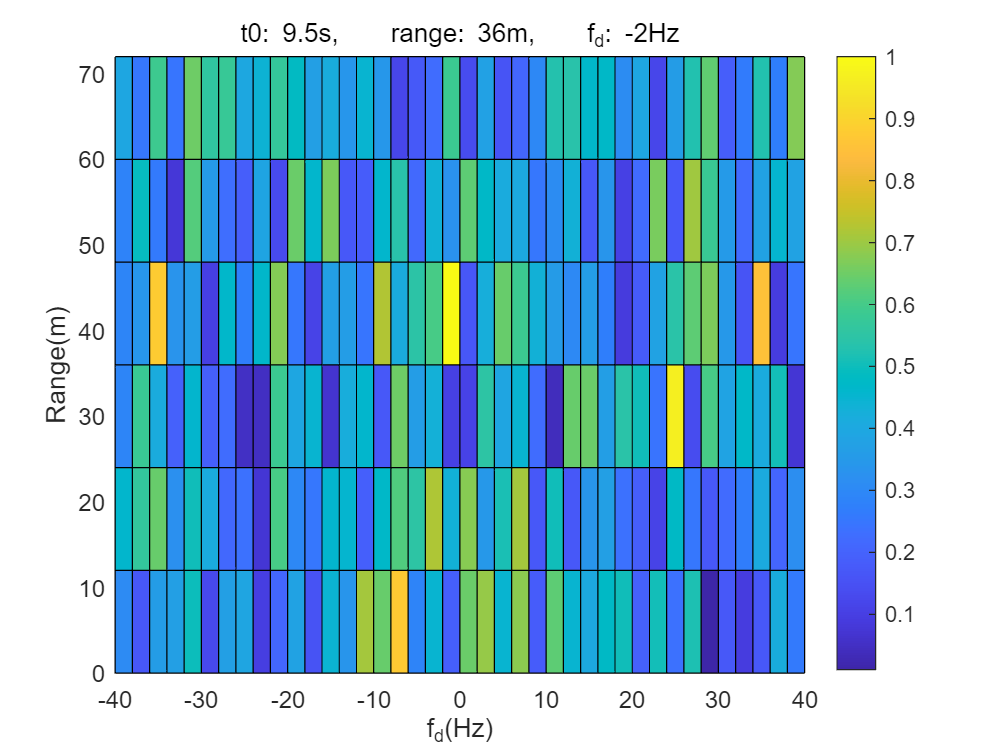

    save("cors_Quicker2/" + sampling_points + "/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end

sampling_points = 10000;
hiti = 0;
hitj = 0;
acci = 1;
accj = 1;
for index = 1:96
    dataStruct1 = load("cors/cors" + index + ".mat");  
    cors1 = dataStruct1.cors;

    dataStruct2 = load("cors_Quicker2/" + sampling_points + "/cors" + index + ".mat");
    cors2 = dataStruct2.cors;

    max1 = -1;
    maxi1 = -1;
    maxj1 = -1;

    max2 = -1;
    maxi2 = -1;
    maxj2 = -1;

    for i = 1:7
        for j = 1:41
            if (cors1(i, j) > max1)
                max1 = cors1(i, j);
                maxi1 = i;
                maxj1 = j;
            end

            if (cors2(i, j) > max2)
                max2 = cors2(i, j);
                maxi2 = i;
                maxj2 = j;
            end
        end
    end

    if (maxi1 == maxi2)
        hiti = hiti + 1;
    else
        acci = acci - abs(maxi1 - maxi2) / (7 * 96);
    end

    if (maxj1 == maxj2) 
        hitj = hitj + 1;
    else
        accj = accj - abs(maxj1 - maxj2) / (41 * 96);
    end
end

disp("hit_tau: " + (hiti / 96 * 100) + "%")

hit_tau: 85.4167%


disp("acc_tau: " + (acci * 100) + "%")

acc_tau: 94.7917%


disp("hit_fd: " + (hitj / 96 * 100) + "%")

hit_fd: 78.125%


disp("acc_fd: " + (accj * 100) + "%")

acc_fd: 96.5955%
